# MaxWell Matlab Toolboxes Tutorials

by Elena Gronskaya [updated 31.01.2020]

### PART I: Data Structure

Welcome! This tutorial will take you through the structure of the recording files. We will see how to access and extract the raw data and spike information and do some basic plotting of  electrode configurations. Two types of recordings will be considered in parallel: the** Activity Scan** and the **Network** recording. These tutorials will mainly focus on data recorded with MaxOne in the Legacy format; however,* [side notes]* will be added added in brackets for explaining how to handle new format data recorded with either MaxOne or MaxTwo. 

Sample data (MaxOne, Legacy format) can be downloaded from here: [https://share.mxwbio.com/d/dfcccbd3e5a74d2a8ae8/](https://share.mxwbio.com/d/dfcccbd3e5a74d2a8ae8/)

#### Load the data

The recording files are stored in the HDF5 (.h5) file format. First, set the path to a folder that contains data from an Activity Scan. 

pathFolderActivityScan = 'C:\Users\tlab\Documents\勉強\竹内研\データ\maxone\20230719'; % folder path

You will notice that the folder contains several .h5 files. This is because an Activity Scan is performed by scanning the entire aray in several high-density sections (using all 1024 channels per section). After the Activity Scan, one can choose the 1024 most active electrodes across the entire MEA, and perform a single Network recording. Thus, for the Network data, we set the path to a single file:

pathFileNetwork ='C:\Users\tlab\Documents\勉強\竹内研\データ\maxone\20230719\data.raw.h5'; % file path 

*[In the new data format, the Activity Scan data is stored as a single file. Therefore, the file path instead of the folder path should be set].*

An HDF5 file can be accessed directly in the following way.

% information about the file
networkDataInfo = h5info(pathFileNetwork);
% the raw signal (first 5000 samples for each channel)
networkRawData = h5read(pathFileNetwork,'/sig',[1 1],[5000 1024]); 
% a smaller chunk of data (between 4000 and 5000 samples for each channel)
networkRawData2 = h5read(pathFileNetwork,'/sig',[4000 1],[1000 1024]); 
% the spikes that were detected and stored by the MaxLab Live software
networkSpikes = h5read(pathFileNetwork,'/proc0/spikeTimes');

*[The HDF5 paths for the new data format are different.]*

#### The fileManager 

There is a dedicated script that extracts the data for you (using the functions above) and structures it in an accessible way. This script also has many useful methods such as artifact removal and signal filtering. It is called **fileManager.m **(found in the *+mxw* folder of the MaxWell Matlab Toolboxes) and it is the starting point for any further data analysis with the Toolboxes. 

% create fileManager object for the Activity Scan
activityScanData = mxw.fileManager(pathFolderActivityScan);
% create fileManager object for the Network recording
networkData = mxw.fileManager(pathFileNetwork);

% remove artifacts
activityScanData.removeSpikeArtifacts(300,50);  
networkData.removeSpikeArtifacts(300,50);

% data.removeSpikeArtifcats(amp_thr, pre_post_smpls) 
% amp_thr: threshold for maximum spike amplitude (in uV). All spikes 
% over this threshold are removed.
% pre_post_smpls: number of samples before and after the artifact spike
% within which other spikes are also removed.

*[For MaxTwo data, the well to be analysed can be specified in the following way:*

*activityScanData = mxw.fileManager(pathFolderActivityScan, wellID);*

*networkData = mxw.fileManager(pathFileNetwork, wellID);*

*where wellID is an integer between 1-6.]*

The **fileManager **object contains some key info (how many files in the recording, their names and paths, filter information, etc.) as well as the data itself, organized in four sub-structures:

- fileObj

- rawMap

- processedMap

- extractedSpikes

Note that *networkData* has a single entry for all of the sub-structures above, while *activityScanData* has multiple entries for each of the Activity Scan files. The exception is *processedMap*, which combines the electrode mapping info across all of the files. We can use the mapping data to visualise the location of the electrodes on the MEA.

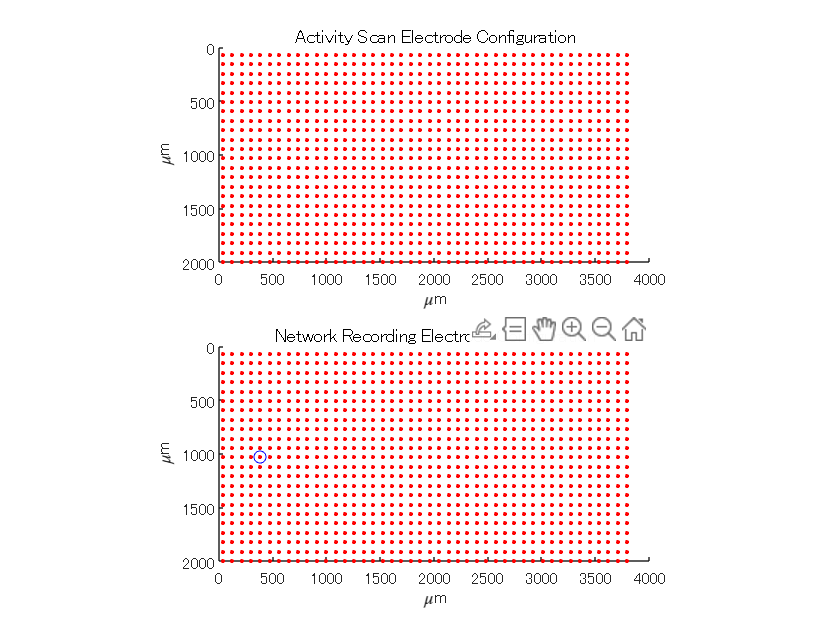

% xy coordinates of electrodes recorded across all of the Activity Scan
% files
x = activityScanData.processedMap.xpos;
y = activityScanData.processedMap.ypos;

% plot xy
figure('color','w');
subplot(211);
plot(x,y,'.r');hold on

% plot the electrodes of just one of the Activity Scan files
%{
filenr = 3;
x = activityScanData.rawMap(filenr).map.x;
y = activityScanData.rawMap(filenr).map.y;
plot(x,y,'.b');
%}

% flip y-axis to match the electrode arrangement on the MEA
axis ij;
% fix aspect ratio between x and y to avoid image distortion
axis equal;
xlim([0 4000]);ylim([0 2000]); box off
xlabel('\mum');ylabel('\mum')
title('Activity Scan Electrode Configuration')

% plot electrode configuration of the Network recording
x = networkData.processedMap.xpos;
y = networkData.processedMap.ypos;

% plot xy
subplot(212);
plot(x,y,'.r');
hold on

% find location of a given channel
ch_nr = 15;
ind = (networkData.rawMap.map.channel==ch_nr);
ch_x = networkData.rawMap.map.x(ind);
ch_y = networkData.rawMap.map.y(ind);
plot(ch_x,ch_y,'ob');

% flip y-axis to match the electrode arrangement on the MEA
axis ij;
% fix aspect ratio between x and y to avoid image distortion
axis equal;
xlim([0 4000]);ylim([0 2000]); box off
xlabel('\mum');ylabel('\mum')
title('Network Recording Electrode Configuration')

Let's go back to the four data sub-structures within the **fileManager **object and look at how they are interrelated:

- fileObj

- rawMap

- processedMap

- extractedSpikes

For *networkD*

*ata*, because there is just one recording file, *networkData.processedMap* contains the same information as *networkData.rawMap.map*. The only difference is that *processedMap* orders the data according to electrode number while *rawMap* orders the data according to channel number. 

rawMap_resorted = sort(networkData.rawMap.map.electrode,'ascend');
isequal(networkData.processedMap.electrode,rawMap_resorted)

ans = logical
   1



% Note! The channel numbers diverge from their indices at one point. 
% Compare the indices with the channel numbers towards the end of the 
% list:
indices = length(networkData.rawMap.map.channel)-5:1:length(networkData.rawMap.map.channel)

indices =         1007        1008        1009        1010        1011        1012


networkData.rawMap.map.channel(indices)'

ans = 1×6 の int32 行ベクトル
   1019   1020   1021   1022   1023   1024


For *activityScanData, processedMap* combines electrode info across all of the files, sorted by electrode number in ascending order.

Now let's look at* fileObj. *Most of the fields within *fileObj *are single pieces of information about the recording file (like the *firstFrameNum *or the* samplingFreq*). The electrode and spike data is stored in just two sub-structures: ***map*** and ***spikes****. *Note that this data is simply a copy of *rawMap.*

isequal(networkData.fileObj.spikes,networkData.rawMap.spikes)

ans = logical
   1


isequal(networkData.fileObj.map,networkData.rawMap.map)

ans = logical
   1



% the same holds true for each of the files in the activityScanData
isequal(activityScanData.fileObj(3,1).spikes,activityScanData.rawMap(3).spikes)

位置 1 のインデックスが配列範囲を超えています。インデックスは 1 を超えてはなりません。

isequal(activityScanData.fileObj(3,1).map,activityScanData.rawMap(3).map)

In the *spikes* sub-structure, you will find three fields of matching lengths: *frameno*, *channel*, and *amplitude*. These arrays pool data from all the spikes detected across all electrodes in a given recording. The spike time stamps are stored as frame numbers in *frameno, *and each spike time is (associated with a corresponding *channel *number and an *amplitude *(in uV). 

In *extractedSpikes, *the spike frame numbers and amplitudes from *rawMap* are reorganized according to ascending electrode number (same electrode order as in *processedMap.electrode*). This is why there are only 1020 rows in* networkData.extractedSpikes* but 6600 rows in *activityScanData.extractedSpikes *(or more, depending on the scan resolution): more electrodes were recorded across all of the Activity Scan files.

So, in summary:

- * fileObj* contains a full copy of *rawMap* data

-  *processedMap* is the same as *rawMap.map*, except it combines mapping data across multiple files (when present) and sorts everything according to electrode number rather than channel number

- *extractedSpikes* groups the spike information according to electrode number  

Now you should be able to easily navigate the *fileManager *data structure, identifying the electrode configuration of a recording as well as the times and amplitudes of all the recorded spikes. In the next tutorial (**PART II: Spikes**), we will go into some basic analysis and plotting of the spike data. You may also be wondering, what happened to the raw signal that we learned how to extract with the h5read function? Indeed, the raw signal is not a part of the *fileManager* object. However, using the *fileManager *methods, you can easily extract and plot the raw and bandpass-filtered data. These methods will be covered in **Part III: Traces**.  